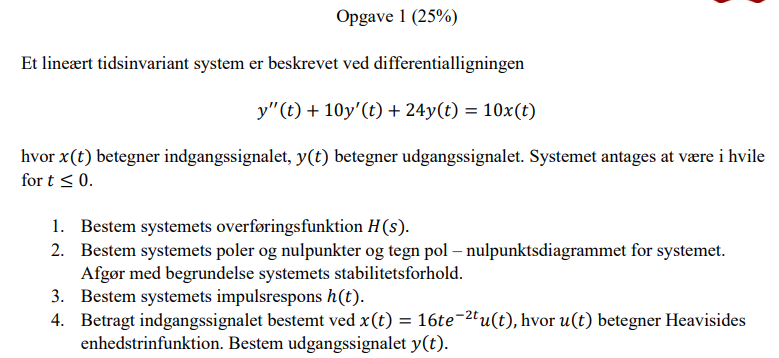

clear all; clc;

### **1. Bestem systemets overføringsfunktion H(s)**

% Definer nødvendige symbolske variable
syms s t;

% Opgave 1: Bestem systemets overføringsfunktion H(s)
% Koefficienterne for differentialligningen:
% y''(t) + 10y'(t) + 24y(t) = 10x(t)
a = [1, 10, 24];  % Koefficienter for y
b = [10];         % Koefficienter for x

disp('Opgave 1: Overføringsfunktion H(s)');

[num, den, H_forklaring] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);

H_s = poly2sym(num, s) / poly2sym(den, s);
%H_s_str = H_forklaring.resultat;

disp(['H(s) = ', char(H_s)]);

### **2. Bestem poler, nulpunkter og stabilitetsforhold**

disp('Opgave 2: Poler og nulpunkter');
forklaringsOutput = ElektroMatBibTrinvis.analyserDifferentialligningMedForklaring(a);

% Poler:
poler = roots(a);
disp('Poler:');
disp(poler);

% Nulpunkter:
nulpunkter = roots(num);
disp('Nulpunkter:');
disp(nulpunkter);

### **3. Bestem systemets impulsrespons h(t)**

disp('Opgave 3: Impulsrespons h(t)');

[h_t, h_forklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(H_s, s, t);

disp(['h(t) = ', char(h_t)]);

### **4. Bestem udgangssignalet y(t)**

disp('Opgave 4: Udgangssignal y(t)');

% Definer indgangssignalet x(t)
x_t = 16*t*exp(-2*t);

% Beregn Laplace-transformationen af x(t)
X_s = laplace(x_t, t, s);

% Beregn udgangssignalet y(t)
[y_t, y_forklaring] = ElektroMatBibTrinvis.beregnUdgangssignalMedForklaring(H_s, X_s, s, t);
disp(['y(t) = ', char(y_t)]);

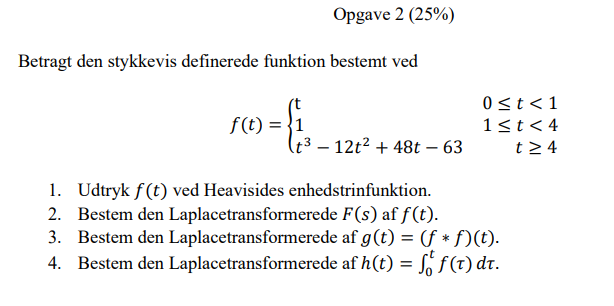

clear all; clc;

### 1. Udtryk f(t) ved Heavisides enhedstrinfunktion

% Definér symbolske variable
syms t

% Definér de tre stykker af funktionen
f1 = t;             % 0 ≤ t < 1
f2 = 1;             % 1 ≤ t < 4
f3 = t^3 - 12*t^2 + 48*t - 63;  % t ≥ 4

% Definér grænserne for intervallerne
graenser = [0, 1, 4, inf];

% Kald den nye funktion
[f_t, forklaring] = ElektroMatBibTrinvis.stykkevisFunktionMedForklaring({f1, f2, f3}, graenser, t);

% Vis resultatet
disp('f(t) udtrykt med Heavisides enhedstrinfunktion:');
disp(f_t);

### **2. Bestem den Laplacetransformerede F(s) af f(t)**

% Beregn Laplacetransformationen
syms s
[F_s, laplace_forklaring] = ElektroMatBibTrinvis.laplaceMedForklaring(f_t, t, s);
disp('Laplacetransformation F(s):');

F_s_simplify = simplify(F_s);
disp(F_s_simplify);

### **3. Bestem den Laplacetransformerede af g(t) = (f * f)(t)**

% Fra delopgave 2 har vi F(s)
% Brug foldningssætningen: L{f*f} = F(s)·F(s)
[G_s, forklaring3] = ElektroMatBibTrinvis.foldningssaetningMedForklaring(F_s, F_s, s, t);

G_s_simplify = simplify(G_s);
disp(G_s_simplify);

### 4. Bestem den Laplacetransformerede af h(t) = ∫₀ᵗ f(τ) dτ

% Antag at F_s er resultatet fra delopgave 2
syms s

% Anvend integralteoremet: L{∫₀ᵗ f(τ) dτ} = F(s)/s
H_s = F_s / s;

% Simplificér resultatet
H_s = simplify(H_s);

disp('Delopgave 4:');
disp('Laplacetransformationen af h(t) = ∫₀ᵗ f(τ) dτ:');
disp('H(s) = F(s)/s =');
disp(H_s);

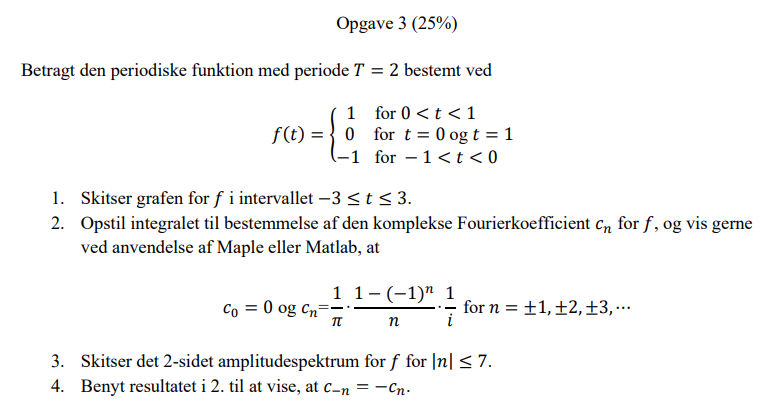

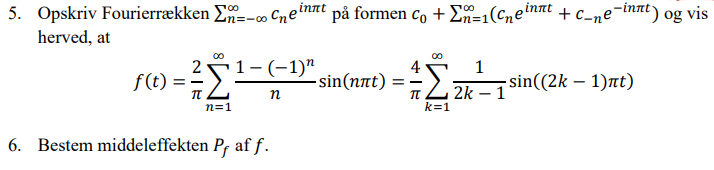

clear all; clc;

### 1.  Skitser grafen for 𝑓 i intervallet −3 ≤ 𝑡 ≤ 3.

% Evaluer funktionen over flere perioder
t_values = -3:0.01:3;
f_values = zeros(size(t_values));

for i = 1:length(t_values)
    t_mod = mod(t_values(i), 2);
    if t_mod == 0 || t_mod == 1
        f_values(i) = 0;
    elseif t_mod > 0 && t_mod < 1
        f_values(i) = 1;
    else % t_mod > 1 && t_mod < 2
        f_values(i) = -1;
    end
end

% Plot grafen
figure;
plot(t_values, f_values, 'LineWidth', 2);
grid on;
title('Graf for f(t) i intervallet [-3, 3]');
xlabel('t');
ylabel('f(t)');

### 2. Opstil integralet til bestemmelse af den komplekse Fourierkoefficient cn for f , og vis gerne ved anvendelse af Maple eller Matlab, 

% Definér den periodiske funktion
syms t
T = 2;
% Definer stykkevis funktion
f(t) = piecewise(0<t<1, 1, t==0 | t==1, 0, -1<t<0, -1);

% Beregn Fourier-koefficienter
[cn, forklaringsOutput] = ElektroMatBibTrinvis.fourierKoefficienterMedForklaring(f, t, T);

### 3. Skitser det 2-sidet amplitudespektrum for f for |n|≤ 7.

% Vis amplitudespektrum for |n| ≤ 7
n_values = -7:7;
amplitudes = zeros(size(n_values));

for i = 1:length(n_values)
    n = n_values(i);
    if n == 0
        amplitudes(i) = abs(cn.c0);
    elseif n > 0
        amplitudes(i) = abs(cn.(['c' num2str(n)]));
    else
        amplitudes(i) = abs(cn.(['cm' num2str(abs(n))]));
    end
end

figure;
stem(n_values, amplitudes, 'filled');
grid on;
title('2-sidet amplitudespektrum for |n| ≤ 7');
xlabel('n');
ylabel('|c_n|');

### 4. Benyt resultatet i 2. til at vise, at c−n =−cn.

% Bedre verifikation af c_{-n} = -c_n relationen
disp('Verificering af c_{-n} = -c_n:');
for n = 1:7
    c_n = cn.(['c' num2str(n)]);
    c_neg_n = cn.(['cm' num2str(n)]);
    
    disp(['For n = ' num2str(n) ':']);
    disp(['c_' num2str(n) ' = ' num2str(c_n)]);
    disp(['c_-' num2str(n) ' = ' num2str(c_neg_n)]);
    
    % Håndter special-tilfældet hvor begge er (tæt på) nul
    eps = 1e-10;
    if abs(c_n) < eps && abs(c_neg_n) < eps
        disp(['Både c_' num2str(n) ' og c_-' num2str(n) ' er 0 - relationen c_{-n} = -c_n holder (0 = -0)']);
    else
        disp(['Forhold c_-' num2str(n) '/c_' num2str(n) ' = ' num2str(c_neg_n/c_n)]);
    end
    disp(' ');
end

### 5. 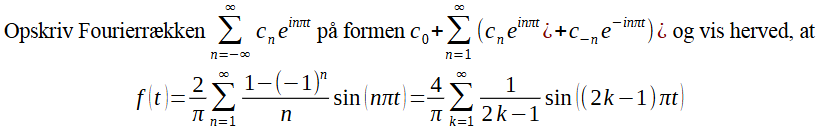

% Omskriv til sinus-række
%N = 20;  % Antal led
%[f_approx, fourierRaekkeOutput] = ElektroMatBibTrinvis.fourierRaekkeMedForklaring(cn, t, T, N);

% Definer funktionen og beregn koefficienter
% Omskriv til trigonometrisk form og identificer mønstre
[series_trig, omskrivningOutput] = ElektroMatBibTrinvis.fourierRaekkeOmskrivningMedForklaring(cn, t, T, 7);

### 6. Bestem middeleffekten P_f af f

% Beregn middeleffekten
[P, effektOutput] = ElektroMatBibTrinvis.parsevalTeoremMedForklaring(cn, 20);  % Bruger 20 led

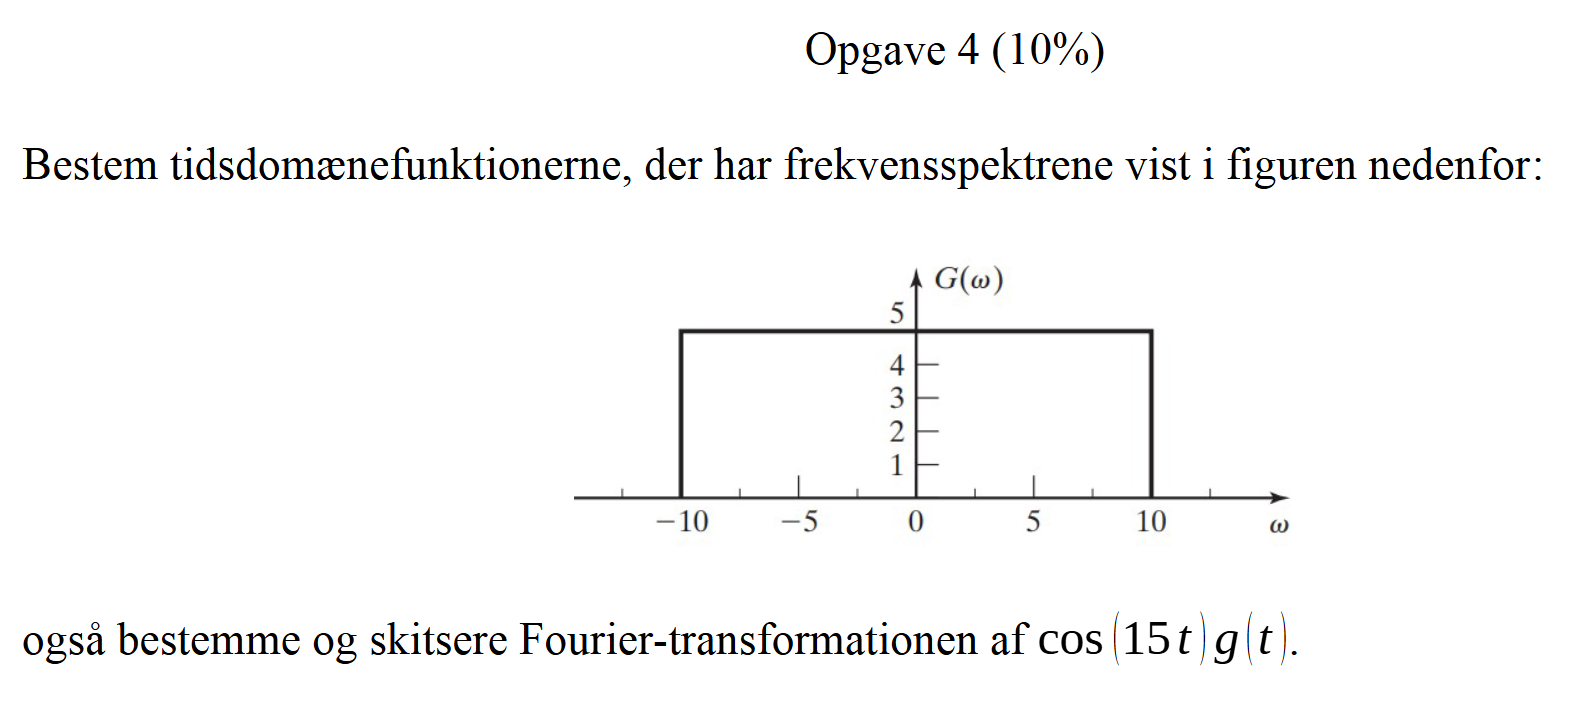

clear all; clc;

disp('=================================================================');
disp('OPGAVE 4: Del 1 - Bestem g(t) fra spektrum G(ω)');
disp('=================================================================');
disp(' ');

syms t omega;

% Fra figuren antager vi: G(ω) = 5 for |ω| ≤ 5, ellers 0
G_omega = 5*(heaviside(omega + 5) - heaviside(omega - 5));

disp('Fra figuren: G(ω) er rektangulær med amplitude 5 og bredde 10');
disp(['G(ω) = ' char(G_omega)]);
disp(' ');

% Brug den nye inverseFourierMedForklaring funktion
[g_t, forklaring1] = inverseFourierMedForklaring(G_omega, omega, t);

disp(' ');
disp('SVAR PÅ DEL 1:');
disp('==============');
disp(['g(t) = ' char(g_t)]);
disp(' ');

disp('=================================================================');
disp('OPGAVE 4: Del 2 - Fourier-transformation af cos(15t)g(t)');
disp('=================================================================');
disp(' ');

% Definer det modulerede signal
moduleret_signal = cos(15*t) * g_t;

% Brug biblioteket til Fourier-transformation
[H_omega, forklaring2] = ElektroMatBibTrinvis.fourierMedForklaring(moduleret_signal, t, omega);

disp(' ');
disp('SVAR PÅ DEL 2:');
disp('==============');
disp(['H(ω) = ' char(H_omega)]);
disp(' ');

disp('=== OPGAVE 4 LØST MED UDVIDET BIBLIOTEK ===');

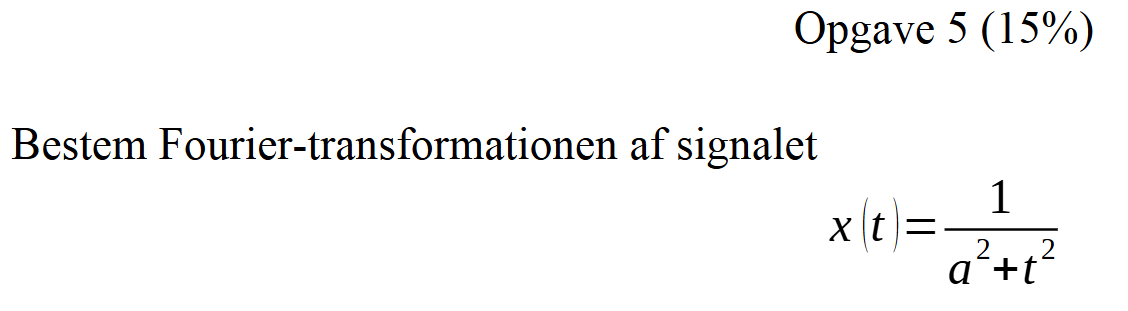

clear all; clc;

disp('=================================================================');
disp('OPGAVE 5: Bestem Fourier-transformationen af signalet');
disp('=================================================================');
disp(' ');

syms t omega a;
assume(a, 'positive');

% Definér signalet
x_t = 1/(a^2 + t^2);

% Brug ElektroMatBibTrinvis biblioteket
[X_omega, forklaring] = ElektroMatBibTrinvis.fourierMedForklaring(x_t, t, omega);

disp(' ');
disp('SVAR PÅ OPGAVE 5:');
disp('================');
disp(['X(ω) = ' char(X_omega)]);
disp(' ');